clear
nElemNodes = 5;
nDOF = 6;
u = sym('u',[nDOF/2,nElemNodes],'real')

$$u = \left(\begin{array}{ccccc} u_{1,1} & u_{1,2} & u_{1,3} & u_{1,4} & u_{1,5}\\ u_{2,1} & u_{2,2} & u_{2,3} & u_{2,4} & u_{2,5}\\ u_{3,1} & u_{3,2} & u_{3,3} & u_{3,4} & u_{3,5} \end{array}\right)$$

theta = sym('theta',[nDOF/2,nElemNodes],'real')

$$theta = \left(\begin{array}{ccccc} \theta_{1,1} & \theta_{1,2} & \theta_{1,3} & \theta_{1,4} & \theta_{1,5}\\ \theta_{2,1} & \theta_{2,2} & \theta_{2,3} & \theta_{2,4} & \theta_{2,5}\\ \theta_{3,1} & \theta_{3,2} & \theta_{3,3} & \theta_{3,4} & \theta_{3,5} \end{array}\right)$$

d = [u;theta]

$$d = \left(\begin{array}{ccccc} u_{1,1} & u_{1,2} & u_{1,3} & u_{1,4} & u_{1,5}\\ u_{2,1} & u_{2,2} & u_{2,3} & u_{2,4} & u_{2,5}\\ u_{3,1} & u_{3,2} & u_{3,3} & u_{3,4} & u_{3,5}\\ \theta_{1,1} & \theta_{1,2} & \theta_{1,3} & \theta_{1,4} & \theta_{1,5}\\ \theta_{2,1} & \theta_{2,2} & \theta_{2,3} & \theta_{2,4} & \theta_{2,5}\\ \theta_{3,1} & \theta_{3,2} & \theta_{3,3} & \theta_{3,4} & \theta_{3,5} \end{array}\right)$$

d(8)

$$ans = u_{2,2}$$

[row,col] = ind2sub(size(d),8)

row = 2

col = 2


d = d(:)

$$d = \left(\begin{array}{c} u_{1,1}\\ u_{2,1}\\ u_{3,1}\\ \theta_{1,1}\\ \theta_{2,1}\\ \theta_{3,1}\\ u_{1,2}\\ u_{2,2}\\ u_{3,2}\\ \theta_{1,2}\\ \theta_{2,2}\\ \theta_{3,2}\\ u_{1,3}\\ u_{2,3}\\ u_{3,3}\\ \theta_{1,3}\\ \theta_{2,3}\\ \theta_{3,3}\\ u_{1,4}\\ u_{2,4}\\ u_{3,4}\\ \theta_{1,4}\\ \theta_{2,4}\\ \theta_{3,4}\\ u_{1,5}\\ u_{2,5}\\ u_{3,5}\\ \theta_{1,5}\\ \theta_{2,5}\\ \theta_{3,5} \end{array}\right)$$

d = reshape(d,nDOF,nElemNodes)

$$d = \left(\begin{array}{ccccc} u_{1,1} & u_{1,2} & u_{1,3} & u_{1,4} & u_{1,5}\\ u_{2,1} & u_{2,2} & u_{2,3} & u_{2,4} & u_{2,5}\\ u_{3,1} & u_{3,2} & u_{3,3} & u_{3,4} & u_{3,5}\\ \theta_{1,1} & \theta_{1,2} & \theta_{1,3} & \theta_{1,4} & \theta_{1,5}\\ \theta_{2,1} & \theta_{2,2} & \theta_{2,3} & \theta_{2,4} & \theta_{2,5}\\ \theta_{3,1} & \theta_{3,2} & \theta_{3,3} & \theta_{3,4} & \theta_{3,5} \end{array}\right)$$


sub2ind(size(d),4,2)

ans = 10


clear
nElem = 10;
nElemNodes = 4;
nDOF = 6;

%%% Mappings %%%
n = 1;
for ii = 1:nElem
    for jj = 1:nElemNodes
        if jj == 1
            n = n+0;
        else
            n = n+1;
        end
        eCONN(jj,ii) = n;
    end
end
eCONN

eCONN =      1     4     7    10    13    16    19    22    25    28
     2     5     8    11    14    17    20    23    26    29
     3     6     9    12    15    18    21    24    27    30
     4     7    10    13    16    19    22    25    28    31



nNodes = max(eCONN(:))

nNodes = 31

nodeDOFS = reshape(1:nNodes*nDOF,nDOF,nNodes)

nodeDOFS =      1     7    13    19    25    31    37    43    49    55    61    67    73    79    85    91    97   103   109   115   121   127   133   139   145   151   157   163   169   175   181
     2     8    14    20    26    32    38    44    50    56    62    68    74    80    86    92    98   104   110   116   122   128   134   140   146   152   158   164   170   176   182
     3     9    15    21    27    33    39    45    51    57    63    69    75    81    87    93    99   105   111   117   123   129   135   141   147   153   159   165   171   177   183
     4    10    16    22    28    34    40    46    52    58    64    70    76    82    88    94   100   106   112   118   124   130   136   142   148   154   160   166   172   178   184
     5    11    17    23    29    35    41    47    53    59    65    71    77    83    89    95   101   107   113   119   125   131   137   143   149   155   161   167   173   179   185
     6    12    18    24    30    36    42    48    54



% Note - we're integrating in the global domain here... in the future we
% will need to integrate over the local domain AND INCLUDE THE JACOBIAN!!

E = 10e6;
b = 1;
h = 1;
nu = 0.3;
shearCorrection = "no";
D = stressStrainMatrix(b,h,E,nu,shearCorrection)

$$D = \left(\begin{array}{cccccc} 10000000 & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{2064888123076923}{536870912} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{2064888123076923}{536870912} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{3579139413333333}{4294967296} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{3579139413333333}{4294967296} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{688296041025641}{1073741824} \end{array}\right)$$

bFun = basisFunction("Bernstein",nElemNodes-1,sym('x'),[0 1])

bFun = struct with fields:
       name: "Bernstein"
     degree: 3
    variate: [1×1 sym]
     domain: [0 1]
      nodes: [0 0.3333 0.6667 1]
      basis: [1×1 symfun]


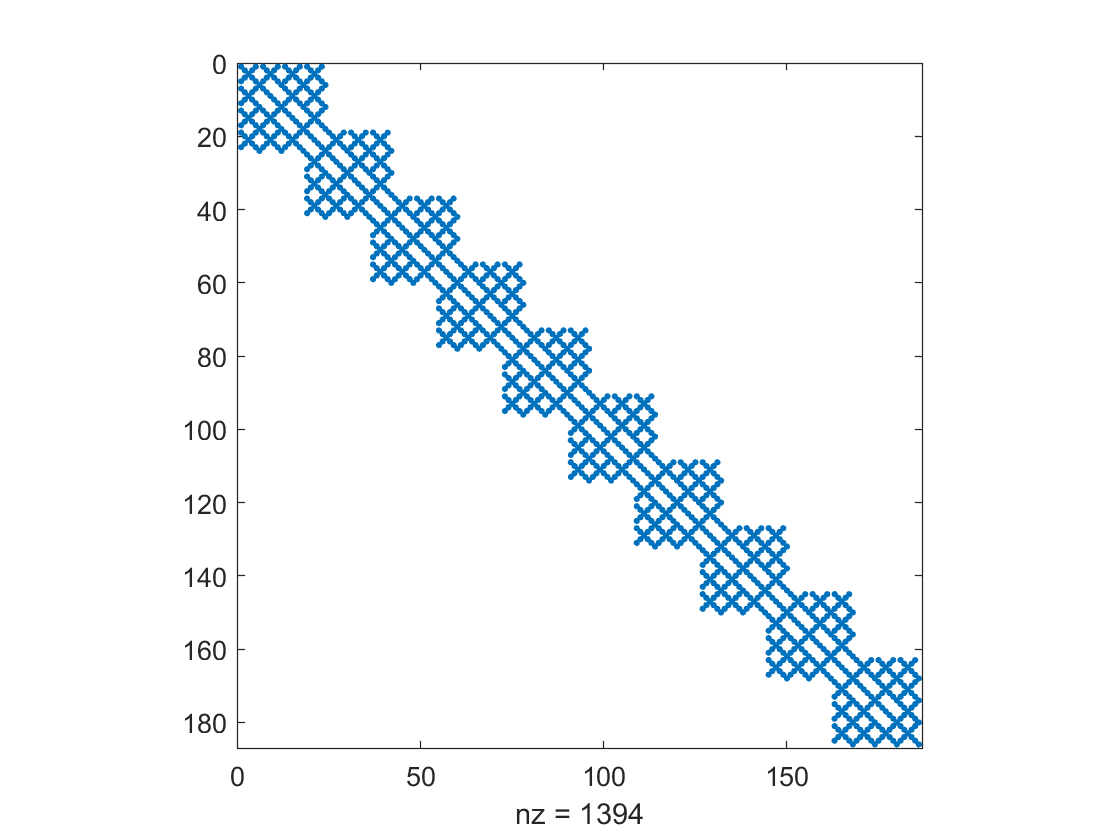

% Given D
for e = 1:nElem
    N = formula(bFun.basis);
    nodal_k = cell(nElemNodes,nElemNodes);
    
    for a = 1:nElemNodes
        % Compute B_a
        Na = N(a);
        Ba = strainDisplacementMatrix(Na);
        for b = 1:nElemNodes
            % Compute B_b
            Nb = N(b);
            Bb = strainDisplacementMatrix(Nb);
            
            % Integrate
            integrand = transpose(Ba) * D * Bb;
            nodal_k{a,b} = int(integrand,[0 1]);
                       
        end
    end
    
%     element_k{e} = [nodal_k{1,1} nodal_k{1,2};...
%                     nodal_k{2,1} nodal_k{2,2}]
      element_k{e} = nodal_k;
end

%%% Assemble Global Matrix %%%
K = sym(zeros(nNodes*nDOF,nNodes*nDOF));
for e = 1:nElem
    for a = 1:nElemNodes
        for b = 1:nElemNodes
            gIDa = nodeDOFS(:,eCONN(a,e));
            gIDb = nodeDOFS(:,eCONN(b,e));
            K(gIDa,gIDb) = K(gIDa,gIDb) + element_k{e}{a,b};
        end
    end
end

K;
spy(K)